Q3

A = [8.3 8.8
     7.4 5.1];
[Vector, Values] = eig(A)

Vector =     0.7988   -0.6671
    0.6016    0.7450


Values =    14.9268         0
         0   -1.5268


Values(1,1) + Values(2,2)

ans = 13.4000

Q8

x0 = 0;
xf = 4;
y0 = 1;
dyf = 3;

dY = @(x, Y) [Y(2); 5*x-2*Y(1)];

z1 = 1;
[x1, y1] = ode45(dY, [x0 xf], [y0, z1]);
y1_end = y1(end,2)

y1_end = 2.1136

z2 = 3;
[x2, y2] = ode45(dY, [x0 xf], [y0, z2]);
y2_end = y2(end,2)

y2_end = 3.7339

z_act = z1 + (z2-z1)/(y2_end-y1_end)*(dyf-y1_end)

z_act = 2.0941

[x,y] = ode45(dY, [x0 xf], [y0, z_act]);
y_end = y(end,2)

y_end = 3.0000

y_0 = y(1,2)

y_0 = 2.0941

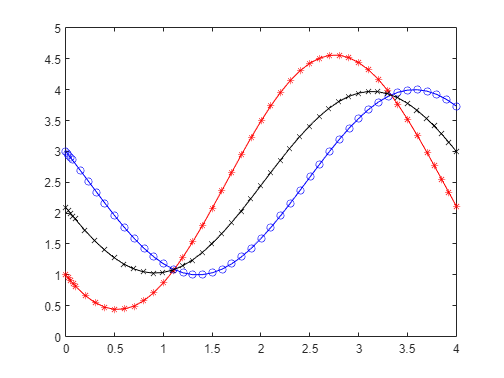


plot(x1, y1(:, 2), "-r*", x2, y2(:,2), "-bo", x, y(:,2), "-kx")

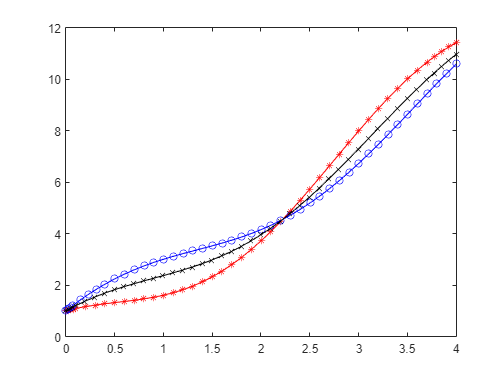

figure()
plot(x1, y1(:, 1), "-r*", x2, y2(:,1), "-bo", x, y(:,1), "-kx")

Q9

I21 = 26.1337;
I22 = 22.7560;
I23 = 21.9301;

I41 = 4/3*I22 - 1/3*I21

I41 = 21.6301

I42 = 4/3*I23 - 1/3*I22

I42 = 21.6548

I61 = 16/15*I42 - 1/15*I41

I61 = 21.6564

Q10

x = [1.45 2.11 6.64 7.54 9.63];
fx = [5.68 4.33 7.26 11.55 9.32];
df = diff(fx)./diff(x)

df =    -2.0455    0.6468    4.7667   -1.0670


sum(df)

ans = 2.3010

Q11

x0 = 2;
xf = 6;
T0 = 200;
Tf = 200;
dx = 1;

dx2 = @(x) 80 - 20*(x-4)^2;

x = x0:dx:xf

x =      2     3     4     5     6



n = (xf-x0)/dx-1;
A = diag(-2*ones(1,n)) + diag(ones(1,n-1),1) + diag(ones(1,n-1),-1)

A =     -2     1     0
     1    -2     1
     0     1    -2


b = [dx2(x(2))*dx^2 - T0; dx2(x(3))*dx^2; dx2(x(4))*dx^2 - Tf]

b =   -140
    80
  -140


Tvals = A\b

Tvals =   100.0000
   60.0000
  100.0000
